clear all

% Set the initial parameters of system
beta_1=deg2rad(0);
system_radius=150;
system_parameters=[beta_1; nan; nan; nan; system_radius];

% Set the optimization parameters
allowed_radius=40;
step=deg2rad(0.1);
step_for_parameters=deg2rad(5);
x=[pi/2;pi/2;pi/2];
version=2;

[phi_set,cartesian_space]=Grid_search_path(deg2rad(5));

Optimization for Lower joints control control case in parallel spherical manipulator

disp('Optimization for Lower joints control control case in parallel spherical manipulator')

Optimization for Lower joints control control case in parallel spherical manipulator


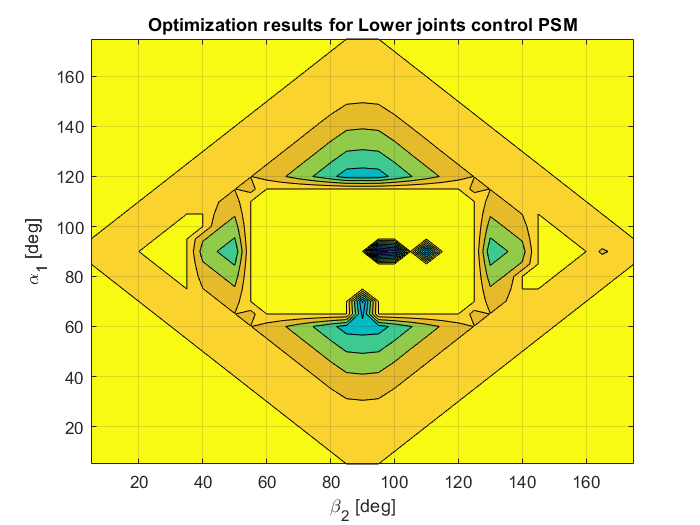

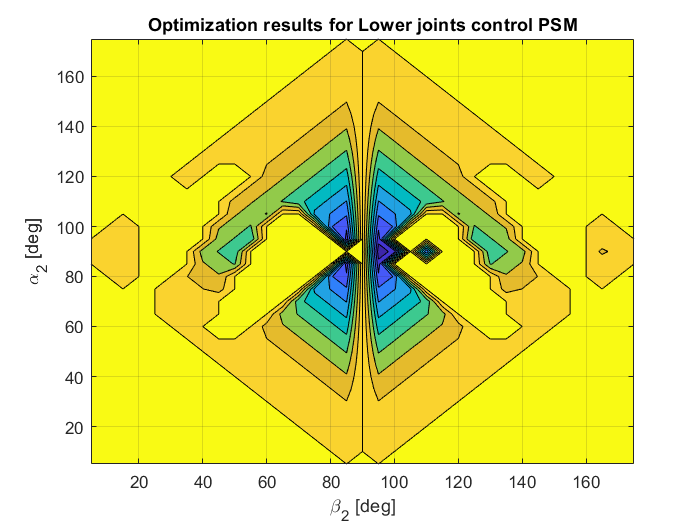

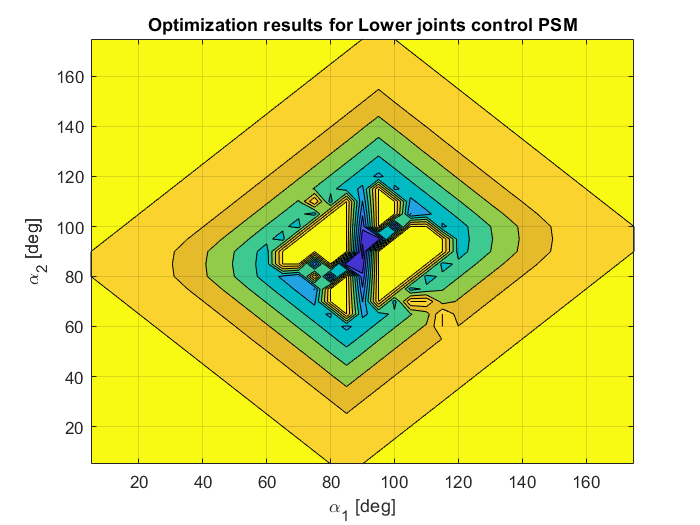

version=1;
[x0]=Grid_search_optimization(system_parameters,allowed_radius,version,step_for_parameters,step);


options = optimoptions('fmincon','Algorithm','sqp');
[x,f_val]=fmincon(@(x)Cost_function_mex(x,system_parameters,step,allowed_radius,version),x0,[],[],[],[],[],[],[],options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fprintf(['Best parameters: beta_1  = %0.2f [deg]\n' ...
         '                 alpha_1 = %0.2f [deg]\n' ...
         '                 alpha_2 = %0.2f [deg]\n'],rad2deg(x(1)),rad2deg(x(2)),rad2deg(x(3)))

Best parameters: beta_1  = 95.00 [deg]
                 alpha_1 = 90.00 [deg]
                 alpha_2 = 90.00 [deg]


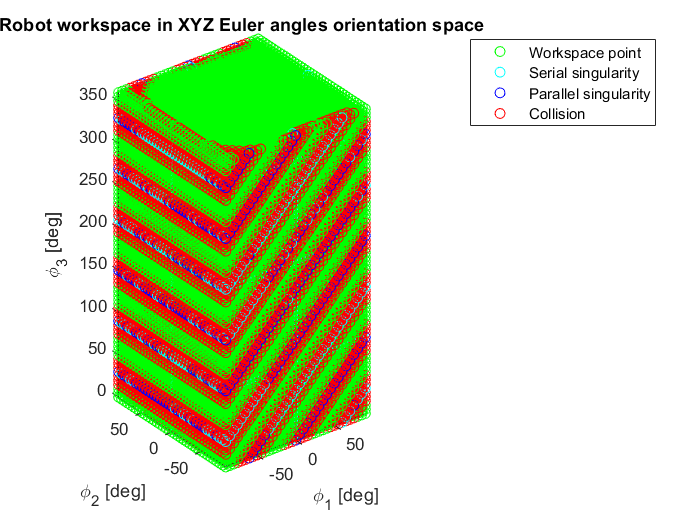

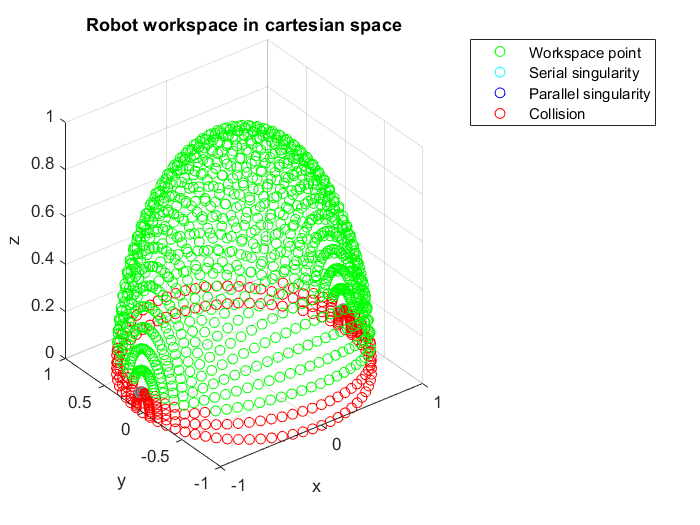


[workspace]=Workspace_calculation([beta_1;x;system_radius],phi_set,allowed_radius,version);
Workspace_visualization(phi_set,cartesian_space,workspace)

Optimization for Mid joints control case in parallel spherical manipulator

disp('Optimization for Mid joints control case in parallel spherical manipulator')

Optimization for Mid joints control case in parallel spherical manipulator


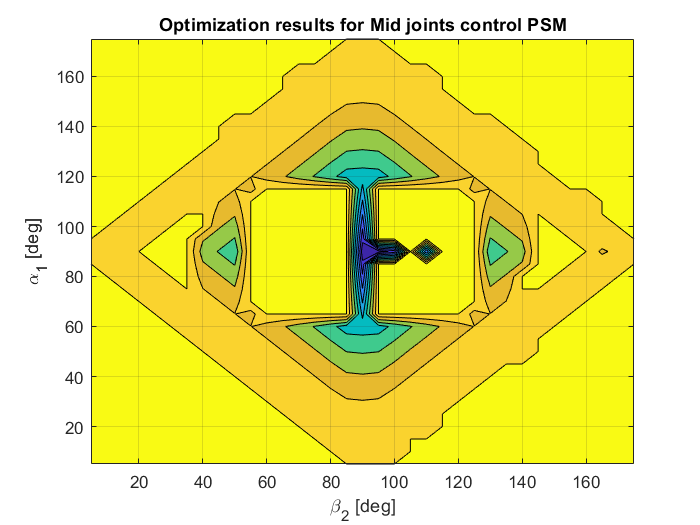

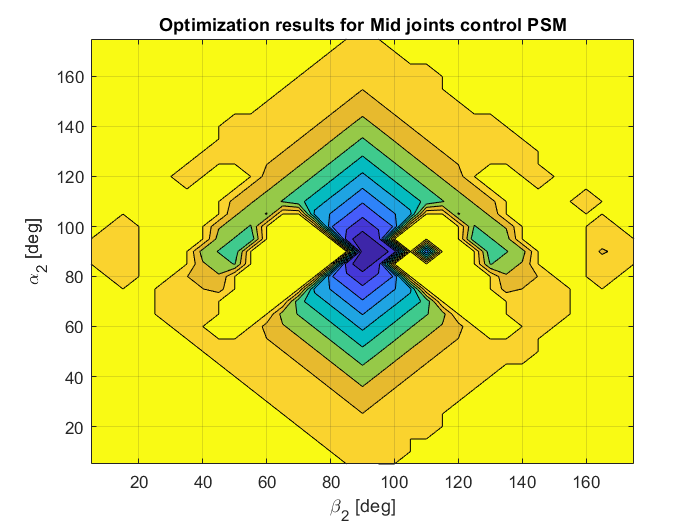

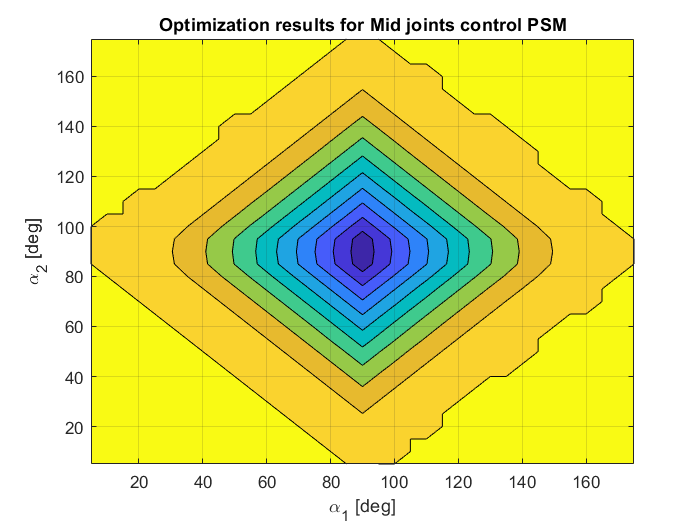

version=2;
[x0]=Grid_search_optimization(system_parameters,allowed_radius,version,step_for_parameters,step);


options = optimoptions('fmincon','Algorithm','sqp');
[x,f_val]=fmincon(@(x)Cost_function_mex(x,system_parameters,step,allowed_radius,version),x0,[],[],[],[],[],[],[],options);


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fprintf(['Best parameters: beta_1  = %0.2f [deg]\n' ...
         '                 alpha_1 = %0.2f [deg]\n' ...
         '                 alpha_2 = %0.2f [deg]\n'],rad2deg(x(1)),rad2deg(x(2)),rad2deg(x(3)))

Best parameters: beta_1  = 90.00 [deg]
                 alpha_1 = 90.00 [deg]
                 alpha_2 = 90.00 [deg]


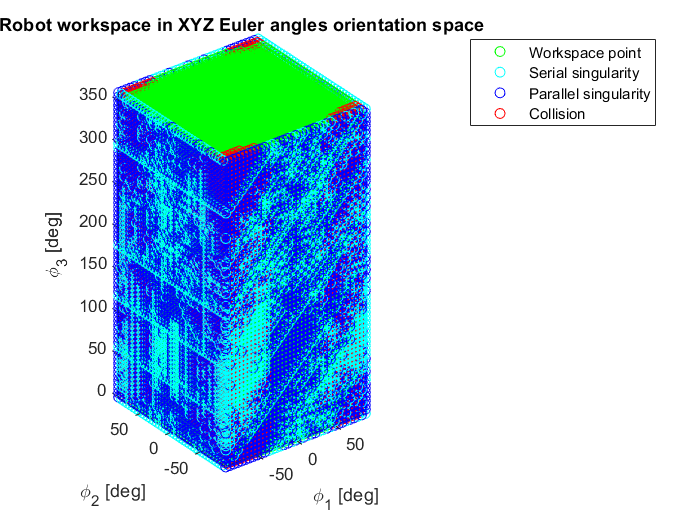

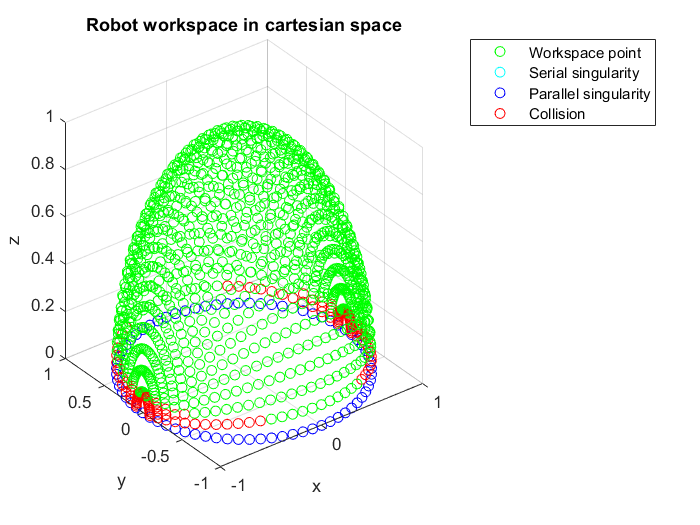


[workspace]=Workspace_calculation([beta_1;x;system_radius],phi_set,allowed_radius,version);
Workspace_visualization(phi_set,cartesian_space,workspace)

function [x_best]=Grid_search_optimization(system_parameters,allowed_radius,version,step_for_parameters,step)
angles=step_for_parameters:step_for_parameters:pi-step_for_parameters;
[beta_2,alpha_1,alpha_2]=meshgrid(angles,angles,angles);
opt_res=zeros(size(beta_2));

best_opt=0;
i_best=0;
j_best=0;
k_best=0;
x_best=zeros(3,1);
for i=1:length(angles)
    for j=1:length(angles)
        for k=1:length(angles)
            x=[beta_2(i,j,k);alpha_1(i,j,k);alpha_2(i,j,k)];
            opt_res(i,j,k)=Cost_function_mex(x,system_parameters,step,allowed_radius,version);
            if best_opt>opt_res(i,j,k)
                best_opt=opt_res(i,j,k);
                i_best=i;
                j_best=j;
                k_best=k;
                x_best=x;
            end
        end
    end
end

[i_size,j_size,k_size]=size(alpha_1);

if version==1
    title_name="Optimization results for Lower joints control PSM";
else
    title_name="Optimization results for Mid joints control PSM";
end

Opt_res_visualization(beta_2(:,:,k_best),alpha_1(:,:,k_best),opt_res(:,:,k_best),i_size,j_size,'\beta_2 [deg]','\alpha_1 [deg]',title_name)
Opt_res_visualization(beta_2(i_best,:,:),alpha_2(i_best,:,:),opt_res(i_best,:,:),j_size,k_size,'\beta_2 [deg]','\alpha_2 [deg]',title_name)
Opt_res_visualization(alpha_1(:,j_best,:),alpha_2(:,j_best,:),opt_res(:,j_best,:),i_size,k_size,'\alpha_1 [deg]','\alpha_2 [deg]',title_name)
end

function []=Opt_res_visualization(x,y,z,x_size,y_size,xlabel_name,ylabel_name,title_name)
X=reshape(x,x_size,y_size);
Y=reshape(y,x_size,y_size);
Z=reshape(z,x_size,y_size);

figure()
contourf(rad2deg(X),rad2deg(Y),Z)
title(title_name)
xlabel(xlabel_name)
ylabel(ylabel_name)
grid on
end